Jordan Grotz

HW4 Configuration Space Assignment

2/6/23

Robot Arm and Movement Definition 

Script will rerun when you change any of the variables. You should see a plot of the arm and obstacle. When the arm is red, it has collided with the obstacle. When it is blue, no obstacle is hit. Then two configuration spaces are generated. One for only checking the end effector, and one that considered the links and other joints of the arm. 

clear
clc
theta1 = 32;
theta2 = -47;
L1 = 3;
L2 = 3;




Create Polygon Obstacle

b_left_corner_x = 2;
b_left_corner_y = 2;
width = 4.2;
height = 5.6;
b_left_corner = [b_left_corner_x,b_left_corner_y];
p1 = b_left_corner;
p2 = b_left_corner+[width,0];
p3 = b_left_corner+[width,height];
p4 = b_left_corner+[0,height];
pgon = polyshape([p1(1),p2(1),p3(1),p4(1)],[p1(2),p2(2),p3(2),p4(2)]);

Workspace Definition

xlimit = [-(L1+L2),(L1+L2)];
ylimit = [-(L1+L2),(L1+L2)];

Plot Arm and Obstacle

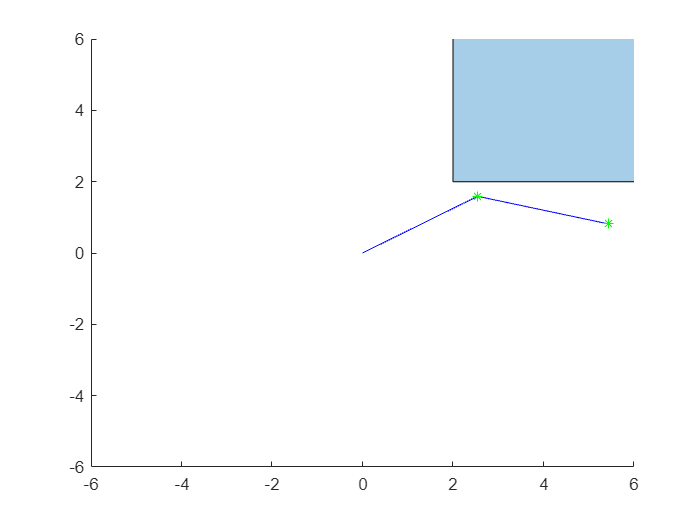

fig = figure;
xlim(xlimit)
ylim(ylimit)
plot(pgon)
[X2,Y2,Xf,Yf] = fkinematics(theta1,theta2,L1,L2);
robot_points = get_robot_points(theta1,theta2,L1,L2,5);
if any(isinterior(pgon,robot_points(1,:),robot_points(2,:)))
    plot_bad_bot(X2,Y2,Xf,Yf);
    xlim([-(L1+L2), L1+L2]);
    ylim([-(L1+L2), L1+L2]);

else
    plot_good_bot(X2,Y2,Xf,Yf);
    xlim([-(L1+L2), L1+L2]);
    ylim([-(L1+L2), L1+L2]);
end

Configuration Space

Two option, one caluclates the configuration space for only considering the end effector, the other one interpolates the links as points, and caluclates a more full config space.

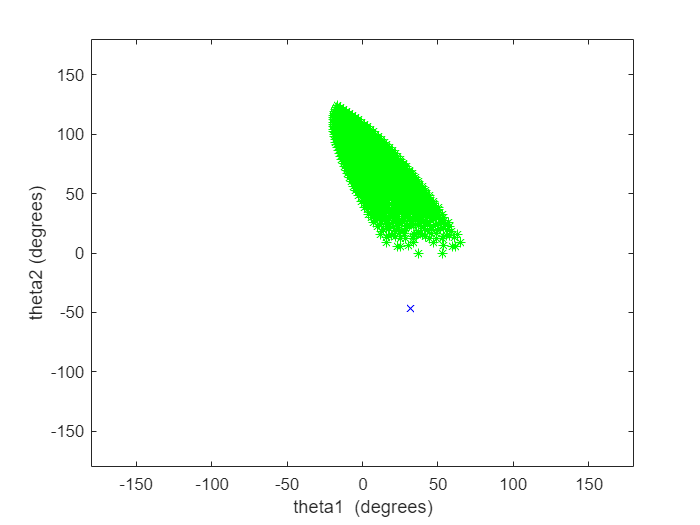

cspace_tip = configuration_space_endpoint(pgon,L1,L2,theta1,theta2);

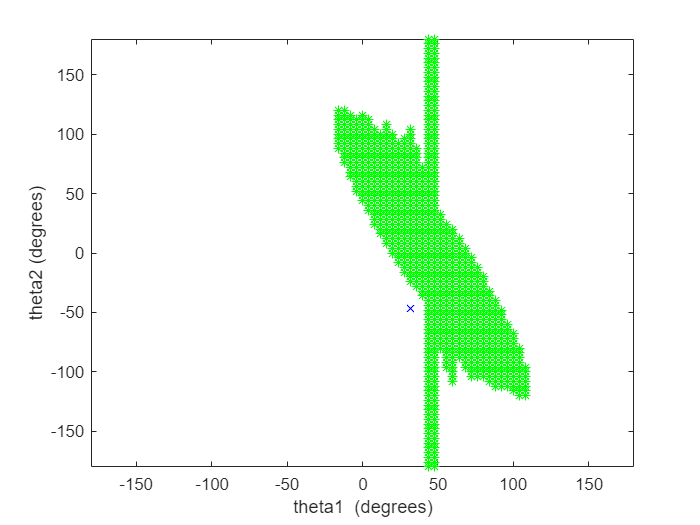

cspace_body = configuration_space_full_bot(pgon,L1,L2,theta1,theta2);

Functions

%Calculates the forward kinematics of the two link arm given the joint
%angles gives location of the first joint, and the end effector

function [x2,y2,xf,yf] = fkinematics(theta1,theta2,L1,L2)
    x2 = (cosd(theta1)*L1);
    y2 = (sind(theta1)*L1);
    xf = x2+(cosd(theta1+theta2)*L2);
    yf = y2+(sind(theta1+theta2)*L2);
end

% plots the robot when determined to be a non obstructed position
function plot_good_bot(x2,y2,xf,yf)
    hold on
    %draw lines
    plot([0,x2,xf],[0,y2,yf],'-b');
    %draw dots
    plot(x2,y2, "Color", "Green", "Marker", "*")
    plot(xf,yf, "Color", "Green", "Marker", "*")
end

% plots the robot when determined to be an obstructed position
function plot_bad_bot(x2,y2,xf,yf)
    hold on
    %draw lines
    plot([0,x2,xf],[0,y2,yf],'-r');
    %draw dots
    plot(x2,y2, "Color", "Red", "Marker", "*")
    plot(xf,yf, "Color", "Red", "Marker", "*")
end

%calculates the inverse kinematics given the end effector point
%can take array inputs
function [theta1s, theta2s] = inverse_kin(Xfs,Yfs,L1,L2)
    L3 = sqrt(Xfs.^2+Yfs.^2);
    theta2prime = acosd((L1.^2+L2.^2-L3.^2)./(2*L1*L2));
    theta2s = 180-theta2prime;
    alpha = atan2d(Yfs,Xfs);
    beta = acosd((L1.^2+L3.^2-L2.^2)./(2*L1*L3));
    theta1s = alpha-beta;
end

%creates a plot of the configuration space only considering the end
%effector of the two link arm
function [cspace] = configuration_space_endpoint(obstacle,L1,L2,theta1,theta2)
    %max reach of the arm in x direction
    x_spaces = 0:0.1:(L1+L2);
    %max reach of the arm in y direction
    y_spaces = 0:0.1:(L1+L2);
    bad_spaces = zeros(length(x_spaces)*length(y_spaces),2);
    index = 0;
    for xs = x_spaces
        for ys = y_spaces
            if sqrt(xs^2+ys^2) <= L1+L2
                if isinterior(obstacle,xs,ys)
                    index = index + 1;
                    [bad_spaces(index,1),bad_spaces(index,2)] = inverse_kin(xs,ys,L1,L2);
                end
            end
        end
    end
  
    figure;
    plot(bad_spaces(1:index,1),bad_spaces(1:index,2),'*g');
    hold on
    plot(theta1,theta2,'xb')
    hold off
    xlim([-180,180]);
    ylim([-180,180]);
    xlabel("theta1  (degrees)");
    ylabel("theta2 (degrees)");
    cspace = bad_spaces(1:index,:);
end

%creates a plot of the configuration space considering endeffector and
%joints of the arm.
function [cspace] = configuration_space_full_bot(obstacle,L1,L2,theta1,theta2)
    %all options for theta 1
    theta1s = -180:4:180;
    %all options for theta 2
    theta2s = -180:4:180;
    bad_spaces = zeros(length(theta1s)*length(theta2s),2);
    index = 0;
    for t1s = theta1s
        for t2s = theta2s
            %for any joint configuration, get the robot's position and
            %check if any obstruction.
            robot_points = get_robot_points(t1s,t2s,L1,L2,5);
            if any(isinterior(obstacle,robot_points(1,:),robot_points(2,:)))
                index = index + 1;
                bad_spaces(index,1) = t1s;
                bad_spaces(index,2) = t2s;
            end
        end
    end
 
    figure;
    plot(bad_spaces(1:index,1),bad_spaces(1:index,2),'*g');
    hold on
    plot(theta1,theta2,'xb')
    hold off
    xlim([-180,180]);
    ylim([-180,180]);
    xlabel("theta1  (degrees)");
    ylabel("theta2 (degrees)");
    cspace = bad_spaces(1:index,:);
end

%returns an array of multiple points representing the joint positions and a
%linear interpolation of the link positions.
function robot_points = get_robot_points(theta1,theta2, L1,L2,resolution)
    [x2,y2,xf,yf] = fkinematics(theta1,theta2,L1,L2);
    link1_vector = [linspace(0,x2,resolution);linspace(0,y2,resolution)];
     link2_vector = [linspace(x2,xf,resolution);linspace(y2,yf,resolution)];
     robot_points = [link1_vector, link2_vector];
end